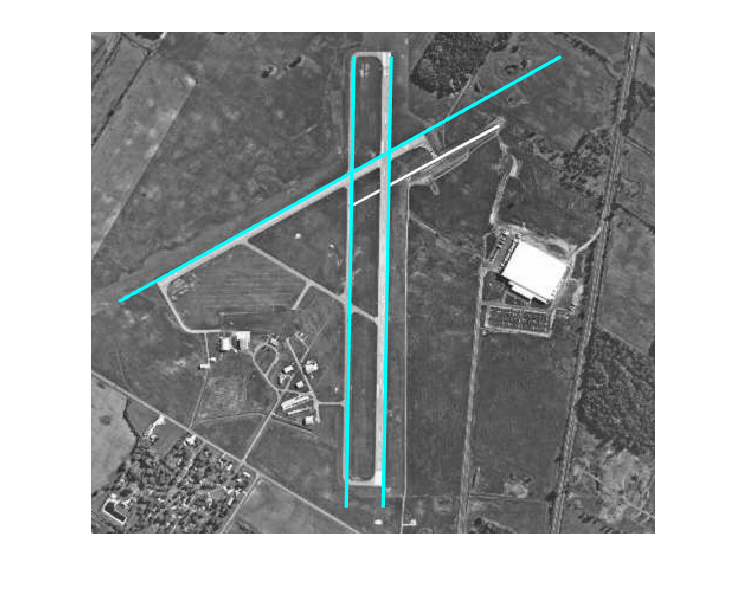

历时 0.449115 秒。


close all;clear;clc;tic;
I = imread('airport.tif');
if size(I,3) == 3
    I = rgb2gray(I);
end
myHoughLine(I,3);toc;

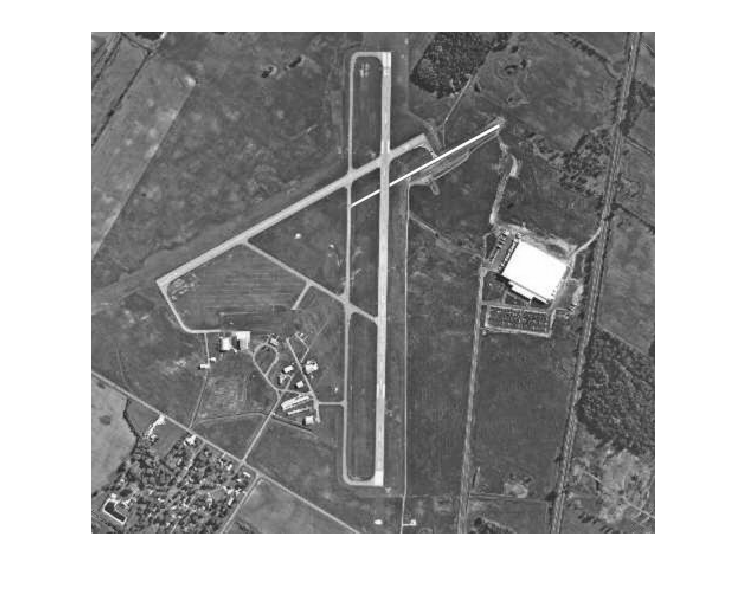

imshow(I);

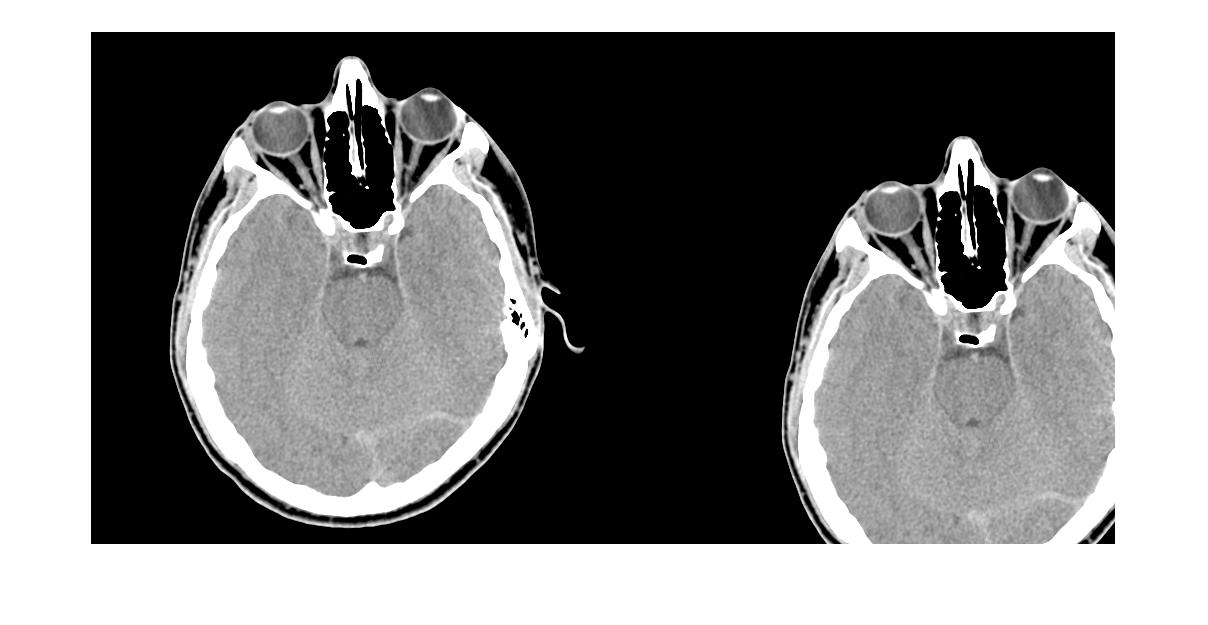

close all;clear;clc;
I = imread( 'head.tif' );
if size(I,3) == 3
    I = rgb2gray(I);
end
transI = imtranslate(I,[100,80]);
figure; imshowpair(I,transI,'montage');

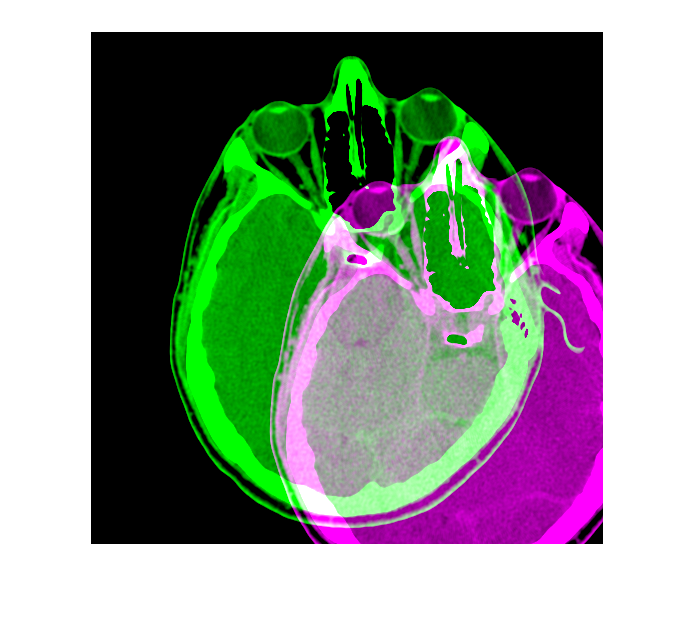

figure; imshowpair(I,transI);

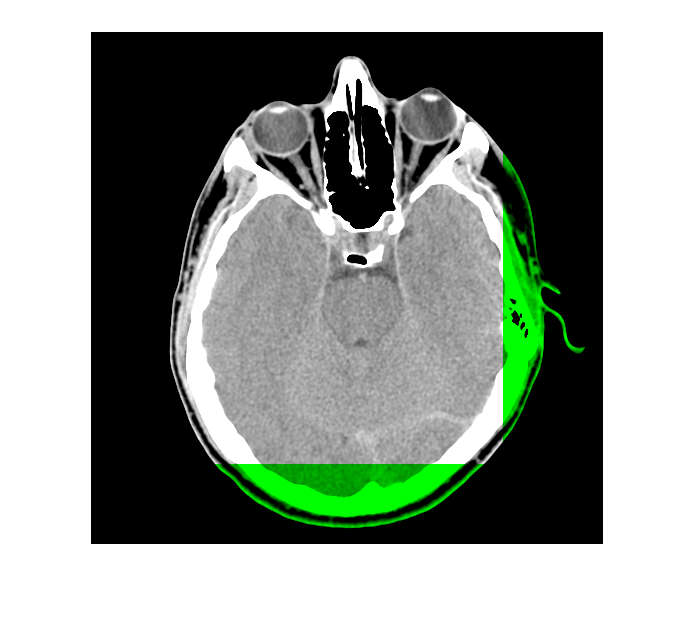

[row,col] = size(I);
FFT1 = fft2(I);
FFT2 = conj(fft2(transI));
FFTR = FFT1 .* FFT2;
FFTRN = (FFTR ./ abs(FFTR));
result = ifft2(FFTRN);
[i,j] = find(result == max(result(:)));
res = [col+1-j,row+1-i];    % 修正坐标
corrI = imtranslate(transI,-res);
figure; imshowpair(I,corrI);

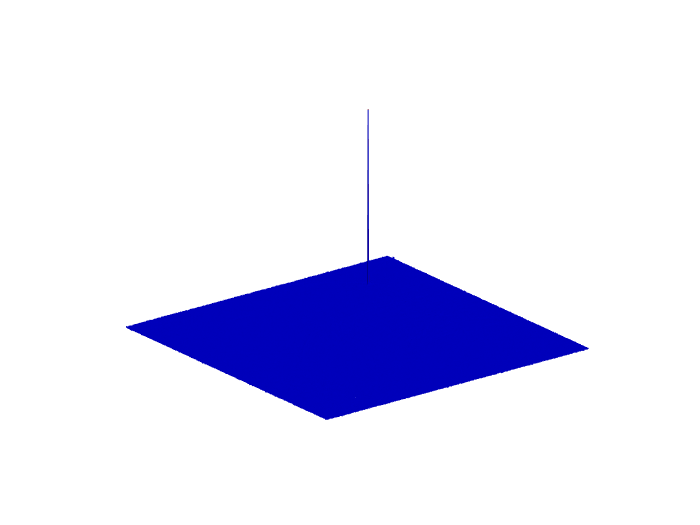

figure; colormap('jet'); mesh(result); axis off;